2 ex

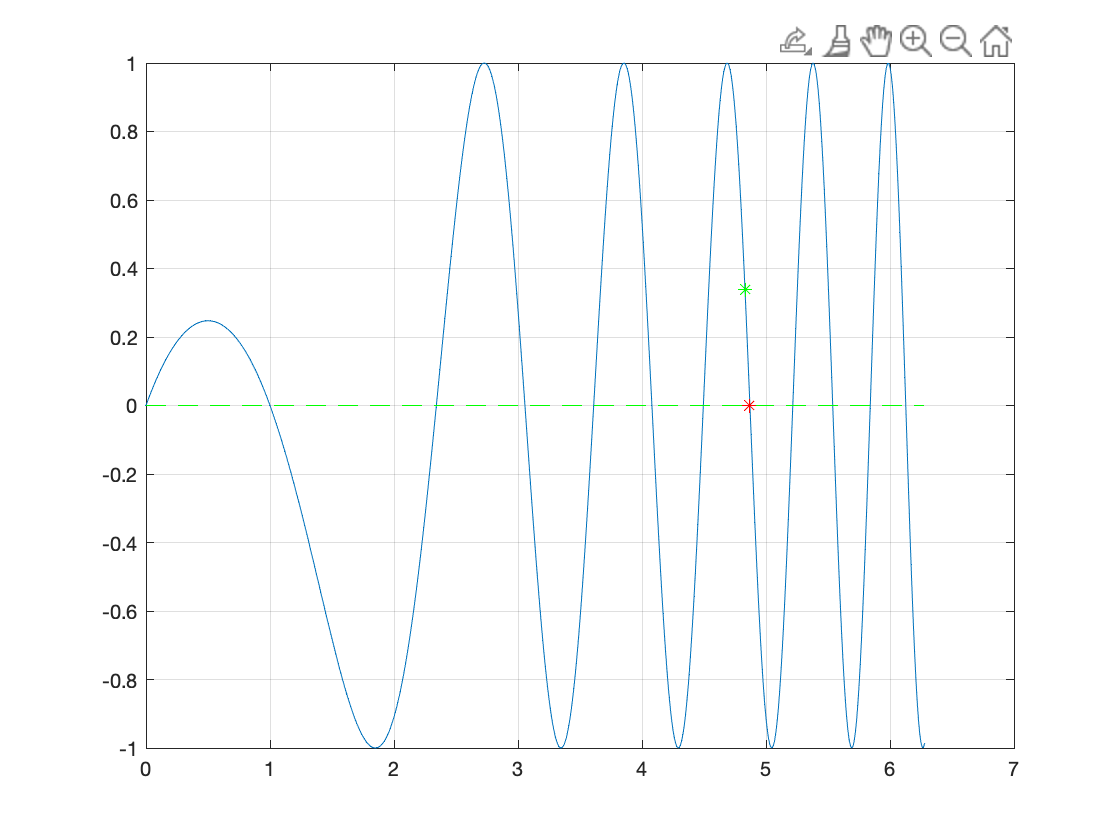

x = 0:0.01:2*pi;
fx = sin(x.*(1-x));
figure
plot(x,fx)
grid on
hold on
plot(x,0*x, "LineStyle","- -", "Color", 'green');

z = ginput(1);
plot(z(1), z(2), "*", "Color",'green');
y = @(x) sin(x.*(1-x));
[zr,fr] = fzero(y,z(1));
hold on

plot(zr,fr, "*", "Color",'red');

syms x 
y =sin(x.*(1-x)) == 0;
[solx,parameters,conditions] = solve(y,x,'ReturnConditions',true)

$$solx = \left(\begin{array}{c} \frac{1}{2}-\frac{\sqrt{4\,\pi \,k+1}}{2}\\ \frac{\sqrt{4\,\pi \,k+1}}{2}+\frac{1}{2} \end{array}\right)$$

$$parameters = k$$

$$conditions = \left(\begin{array}{c} \mathrm{symtrue}\\ \mathrm{symtrue} \end{array}\right)$$